# 训练示例

要演示训练过程，请执行以下命令：

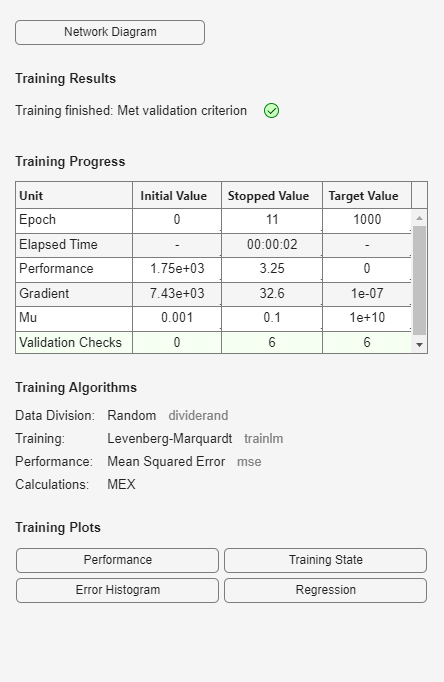

clear
load bodyfat_dataset
net = feedforwardnet(20);
[net,tr] = train(net,bodyfatInputs,bodyfatTargets);

% 请注意，您不需要发出 configure 命令，因为配置是由 train 函数自动完成的。
% 训练期间将出现训练窗口，如下图所示。（如果您不想在训练期间显示此窗口，
% 可以将参数 net.trainParam.showWindow 设置为 false。如果您要在命令行中显示训练信息，可以将参数 net.trainParam.showCommandLine 设置为 true。）
% 此窗口显示数据已使用 dividerand 函数进行划分，
% 并且使用了 Levenberg-Marquardt (trainlm) 训练方法和均方误差性能函数。
% 上面提到过，这些是 feedforwardnet 的默认设置。
% 在训练期间，进度会在训练窗口中不断更新。
% 最关注的是性能、性能梯度的量级和验证检查的数量。
% 梯度的量级和验证检查的数量用于终止训练。
% 当训练达到性能的最小值时，梯度将变得非常小。如果梯度的量级小于 1e-5，训练将停止。
% 该限制可通过设置参数 net.trainParam.min_grad 进行调整。
% 验证检查的数量表示验证性能无法降低的连续迭代次数。如果该数字达到 6（默认值），训练将停止。
% 在本次运行中，您可以看到鉴于验证检查的数量，训练确实停止了。
% 您可以通过设置参数 net.trainParam.max_fail 来更改此条件。
% （请注意，因为初始权重和偏置的随机设置，您的结果可能不同于下图所示的结果。）



% 还有其他条件可用于停止网络训练。下表列出了这些条件。
% 
% 参数   停止条件
% min_grad	最小梯度幅值
% max_fail	验证增加的最大数量
% time	最大训练时间
% goal	最低性能值
% epochs	最大训练轮数（迭代数）

% 如果您点击训练窗口中的 Stop Training 按钮，训练也将停止。
% 如果性能函数在多次迭代中未显著降低，您可能需要这样做。通过重新发出上面所示的 train 命令，始终可以继续训练。它将从上一次运行完成的状态继续训练网络。
% 在训练窗口中，您可以访问四个图：性能、训练状态、误差直方图和回归。性能图显示性能函数值对迭代次数的图。它对训练、验证和测试性能绘图。训练状态图显示其他训练变量的进度，例如梯度幅值、验证检查的数量等。误差直方图显示网络误差的分布。回归图显示网络输出和网络目标之间的回归。您可以使用直方图和回归图来验证网络性能，如分析训练后的浅层神经网络性能中所述。

## 使用网络

在网络经过训练和验证后，网络对象可用于计算网络对任何输入的响应。例如，如果您要在构造数据集中找到对第五个输入向量的网络响应，可以使用以下命令

a = net(bodyfatInputs(:,5))

a = 30.1477

% a =   27.3740
% 如果尝试此命令，输出可能会有所不同，具体取决于网络初始化时随机数生成器的状态。下面，调用网络对象来计算体脂数据集中所有输入向量的并发集合的输出。这是批量模式的仿真，其中所有输入向量都放在一个矩阵中。这比一次提交一个向量要高效得多。

a = net(bodyfatInputs);
% 每次训练神经网络时，由于初始权重和偏置值不同，并且将数据划分为训练集、验证集和测试集的方式也不同，可能会产生不同的解。因此，针对同一问题训练的不同神经网络对同一输入可能给出不同输出。为确保找到准确度良好的神经网络，需要多次重新训练。
% 
% 如果需要更高的准确度，可以采用几种其他方法来改进初始解。有关详细信息，请参阅提高浅层神经网络泛化能力，避免过拟合。

## 分析训练后的浅层神经网络性能

本主题介绍典型浅层神经网络工作流的一部分。有关详细信息和其他步骤， 请参阅多层浅层神经网络与反向传播训练。 要了解如何监控深度学习训练进度，请参阅监控深度学习训练进度。

% 当训练与应用多层浅层神经网络中所述的训练结束后，
% 您可以检查网络性能，并确定是否需要对训练过程、网络架构或数据集进行任何更改。
% 首先检查训练记录 tr，这是训练函数返回的第二个参数。

tr

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [3 4 5 7 8 10 11 14 15 16 17 18 19 20 21 22 23 26 28 29 30 31 32 34 36 37 38 39 41 42 43 44 48 49 51 52 53 57 59 61 62 65 67 68 69 70 71 72 73 74 75 76 77 79 80 81 82 84 85 87 88 90 91 92 93 94 95 96 97 98 99 100 103 … ] (1×176 double)
          valInd: [1 9 12 13 33 35 40 45 47 54 56 58 63 78 86 89 101 102 114 115 118 119 121 130 134 135 146 148 159 176 180 184 185 194 203 220 230 237]
         testInd: [2 6 24 25 27 46 50 55 60 64 66 83 104 112 113 133 142 150 151 154 157 163 165 170 174 177 178 179 181 215 217 229 232 234 235 238 245 249]
            stop: 'Training finished: Met validation criterion'
      num_epochs: 11
       trainMask: {[NaN NaN 1 1 1 NaN 1 1 NaN 1 1 NaN NaN 1 1 1 1 1 1 1 1 1 1 NaN NaN 1 

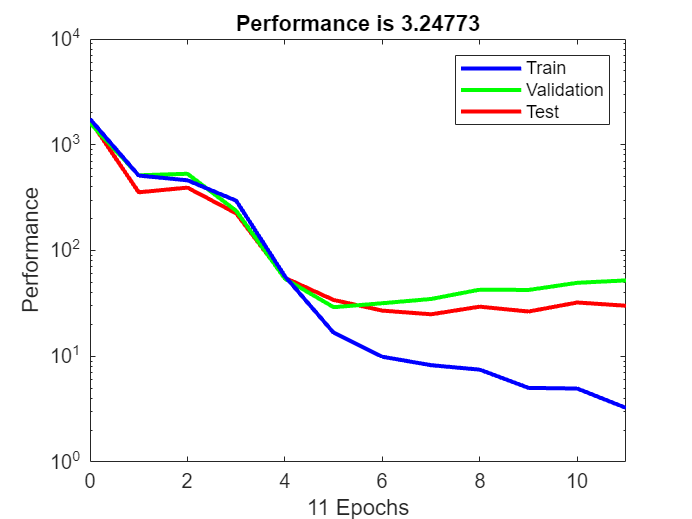

% tr = struct with fields:
%         trainFcn: 'trainlm'
%       trainParam: [1x1 struct]
%       performFcn: 'mse'
%     performParam: [1x1 struct]
%         derivFcn: 'defaultderiv'
%        divideFcn: 'dividerand'
%       divideMode: 'sample'
%      divideParam: [1x1 struct]
%         trainInd: [1x176 double]
%           valInd: [1x38 double]
%          testInd: [1x38 double]
%             stop: 'Validation stop.'
%       num_epochs: 9
%        trainMask: {[1x252 double]}
%          valMask: {[1x252 double]}
%         testMask: {[1x252 double]}
%       best_epoch: 3
%             goal: 0
%           states: {1x8 cell}
%            epoch: [0 1 2 3 4 5 6 7 8 9]
%             time: [1x10 double]
%             perf: [1x10 double]
%            vperf: [1x10 double]
%            tperf: [1x10 double]
%               mu: [1x10 double]
%         gradient: [1x10 double]
%         val_fail: [0 0 0 0 1 2 3 4 5 6]
%        best_perf: 12.3078
%       best_vperf: 16.6857
%       best_tperf: 24.1796

% 此结构体包含关于网络训练的所有信息。例如，tr.trainInd、tr.valInd 和 tr.testInd 
% 分别包含训练、验证和测试集中使用的数据点的索引。
% 如果您要使用相同的数据划分重新训练网络，
% 可以将 net.divideFcn 设置为 'divideInd'，
% net.divideParam.trainInd 设置为 tr.trainInd，
% net.divideParam.valInd 设置为 tr.valInd，
% net.divideParam.testInd 设置为 tr.testInd。

% tr 结构体还在训练过程中跟踪几个变量，如性能函数值、梯度幅值等。
% 您可以通过 plotperf 命令，使用训练记录来绘制性能进度图：

plotperf(tr)

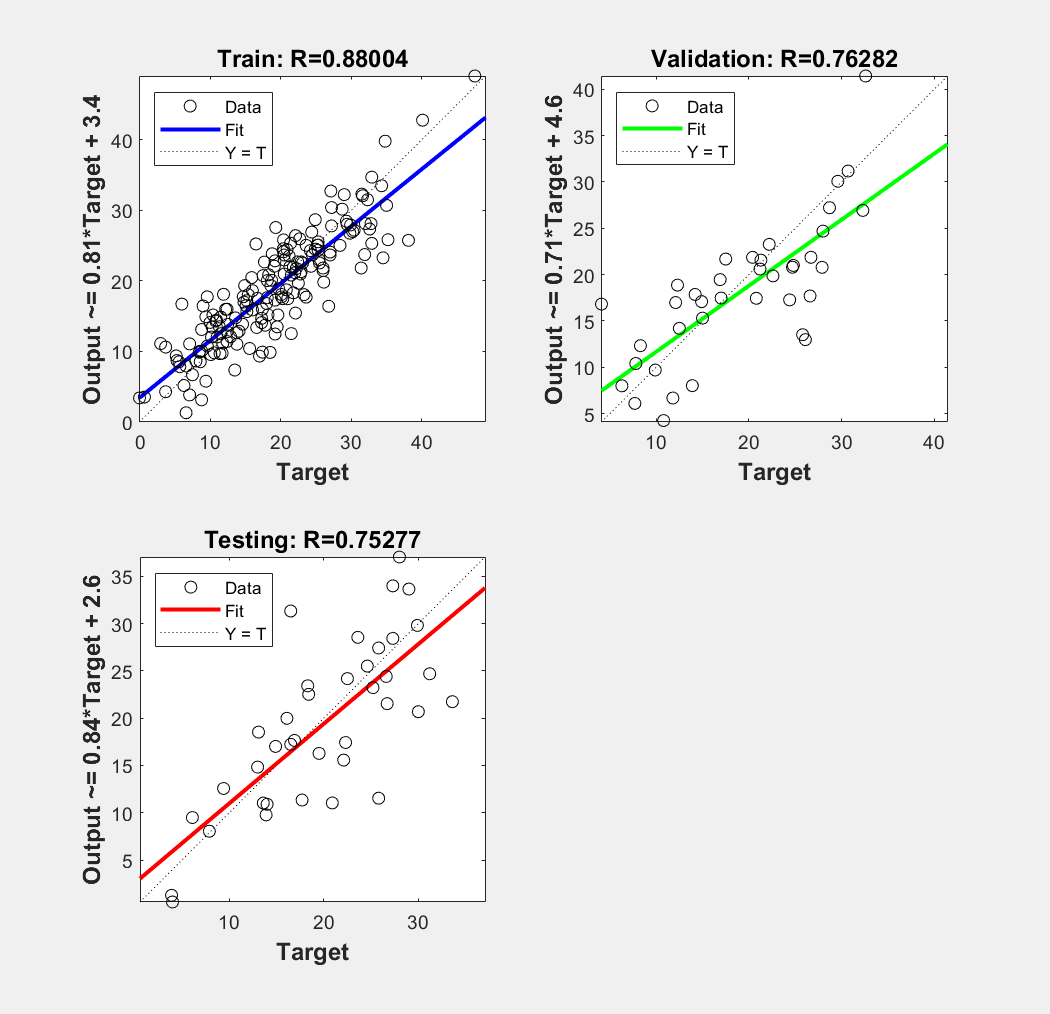

% Figure Training Record contains an axes. The axes with title Performance is 6.3064 
% contains 4 objects of type line.
% These objects represent Test, Validation, Train.

% 属性 tr.best_epoch 表示验证性能达到最小值时所处的迭代。
% 在训练停止之前，训练继续进行了 6 次迭代。
% 此图并未表明训练有任何重大问题。验证曲线和测试曲线非常相似。
% 如果测试曲线在验证曲线增大之前显著增大，则可能发生了一些过拟合。
% 验证网络的下一步是创建一个回归图，该图显示网络输出和目标之间的关系。
% 如果训练是完美的，则网络输出和目标将完全相等，但在实践中极少出现这种完美关系。
% 对于体脂示例，我们可以使用以下命令创建回归图。
% 第一个命令计算经过训练的网络对数据集中所有输入的响应。
% 接下来的六个命令提取属于训练、验证和测试子集的输出和目标。
% 最后一个命令为训练、测试和验证创建三个回归图。

bodyfatOutputs = net(bodyfatInputs);
trOut = bodyfatOutputs(tr.trainInd);
vOut = bodyfatOutputs(tr.valInd);
tsOut = bodyfatOutputs(tr.testInd);
trTarg = bodyfatTargets(tr.trainInd);
vTarg = bodyfatTargets(tr.valInd);
tsTarg = bodyfatTargets(tr.testInd);
figure;
plotregression(trTarg, trOut, 'Train', vTarg, vOut, 'Validation', tsTarg, tsOut, 'Testing')

% Figure Regression (plotregression) contains 3 axes.
% Axes 1 with title Train: R=0.91107 contains 3 objects of type line. 
% These objects represent Y = T, Fit, Data. 
% Axes 2 with title Validation: R=0.8456 contains 3 objects of type line.
% These objects represent Y = T, Fit, Data.
% Axes 3 with title Testing: R=0.87068 contains 3 objects of type line. 
% These objects represent Y = T, Fit, Data.

% 这三个图表示训练、验证和测试数据。每个图中的虚线表示完美结果 - 输出 = 目标。
% 实线表示输出和目标之间的最佳拟合线性回归线。R 值表示输出和目标之间的关系。
% 如果 R = 1，这表明输出和目标之间存在准确的线性关系。
% 如果 R 接近于零，则输出和目标之间没有线性关系。
% 
% 对于此示例，训练数据表明拟合良好。验证和测试结果也显示较大的 R 值。
% 散点图有助于显示某些数据点的拟合效果很差。
% 例如，测试集中有一个数据点的网络输出接近 35，而对应的目标值约为 12。
% 下一步将是调查此数据点，以确定它是否表示外插点（即，它是否在训练数据集之外）。
% 如果它是外插点，则应将其包括在训练集中，并且应采集额外的数据以用于测试集中。

## 改进结果

如果网络不够准确，您可以尝试重新初始化网络并进行训练。 每次初始化前馈网络时，网络参数都不同，并且可能产生不同解。

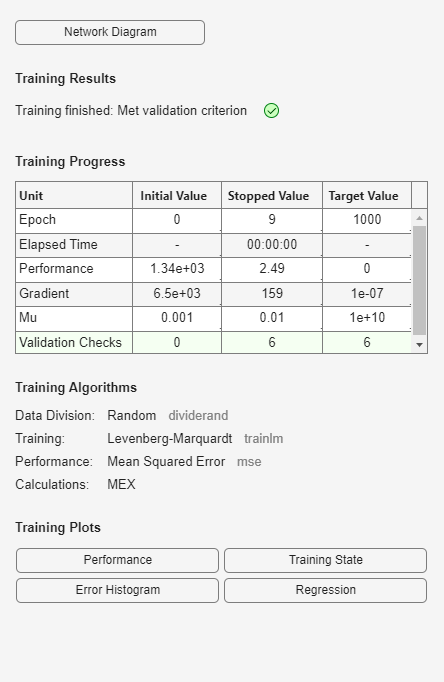

net = init(net);
net = train(net, bodyfatInputs, bodyfatTargets);

% 作为另一种方法，您可以将隐藏神经元的数量增加到 20 个以上。
% 隐藏层中的神经元数量越多，网络的灵活度就越高，因为网络可以优化更多参数。
% 请逐渐增加层大小。% 如果将隐含层设置得太大，可能会导致问题的特征不清晰，
% 并且网络必须优化的参数数目多于约束这些参数的数据向量数目。）


% 第三个选择是尝试不同训练函数。例如，与使用早停法相比，
% 使用 trainbr 的贝叶斯正则化训练有时可以提供更好的泛化能力。
% 最后，尝试使用额外的训练数据。为网络提供额外数据，
% 则生成的网络更可能对新数据具有更强的泛化能力。